# Experiments Analysis & Comparison with simulations

**⚠️ IMPORTANT: **the data associated in the `sim_esp####` files are not experimental ones, do not use in this folder ⚠️

**Before exporting the figures select the time interval that allow to see well the carachteristics of the response!!! curently we plot up to t_max but something is hard to see we may need to zoom in!!!**

This script is used to plot all the experimental data collected in the laboratory sessions and compare them with analogous simulated results whenever possible.

**USAGE:**

- **First run the ****"Setting Path" section**** from inside the folder "Completed Project".**

- **Then Go to the experiment of interest and run the corresponding section. **

## Index

- PP Stabilization with Observer

- PP Tracking with Observer

- PP Tracking with KF

- LQ Stabilization with Observer

- LQ Stabilization with KF

- LQ Tracking with Observer

- LQ Tracking with KF

## Setting the path

(pay attention being in the complete poject folder)

clear 
close all

% measurements and reference
addpath("data/theta_esp/")
addpath("data/alpha_esp/")
addpath("data/theta_d_esp/")
addpath("data/alpha_d_esp/")
addpath("data/theta_ref/")
% observer
addpath("data/theta_est/")
addpath("data/alpha_est/")
addpath("data/theta_d_est/")
addpath("data/alpha_d_est/")
% input-time
addpath("data/voltage_esp/")
addpath("data/t_esp/")

t_max = 60; % global variables for plots

## Pole Placement

### Stabilization

#### With Observer

back to index

[Time_vec,uin,theta_ref,ysim,xhat,ymeas,z0,N] = experimental_data_processing(201);

z0

z0 =          0
   -0.0031
         0
         0


Time_vec(end)

ans = 61.0490

[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim] = sim_data_processing(201);
z0_sim

z0_sim =          0
   -0.0031
         0
         0


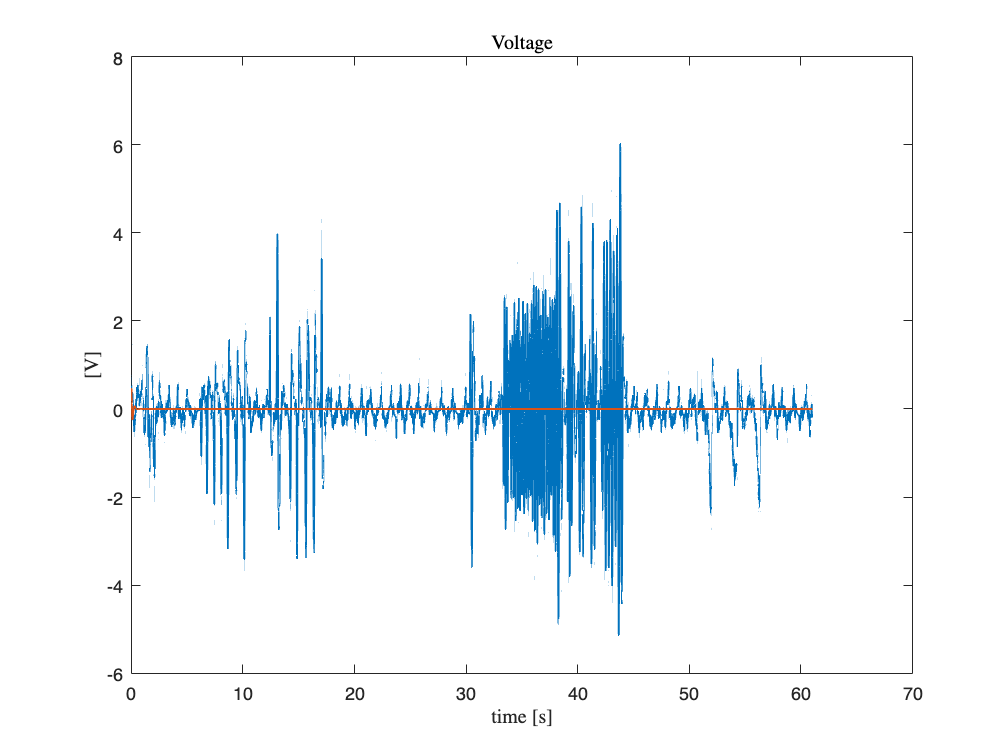

% plot the voltage signal
figure,plot(Time_vec(1:N_sim),uin(1:N_sim),Time_vec_sim(1:N_sim),uin_sim,LineWidth=1);
legend('meas','sim')
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')

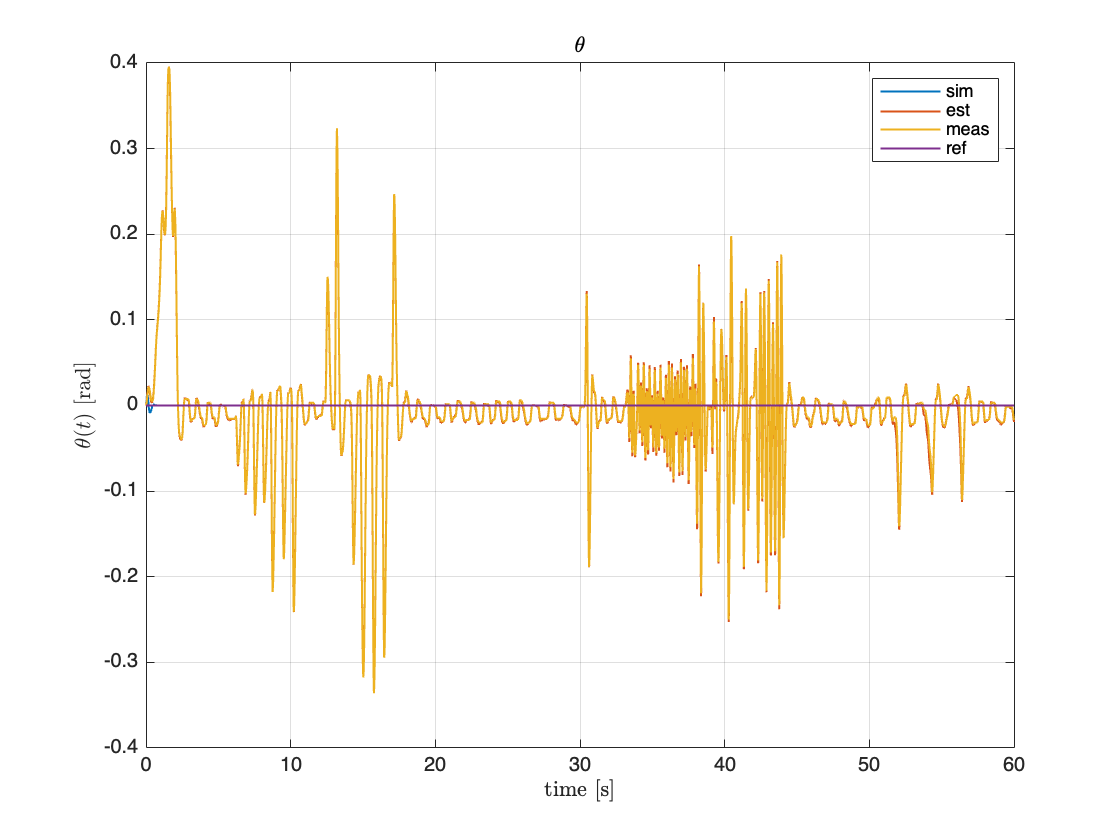

grid on

% plot theta - theta_est - theta_ref 
figure,plot(Time_vec_sim,ysim(1,:),Time_vec(1:N_sim),xhat(1,1:N_sim),Time_vec(1:N_sim),ymeas(1,1:N_sim),Time_vec,theta_ref,LineWidth=1)
title('$\theta$','Interpreter','latex')
legend('sim','est','meas','ref')
xlabel('time [s]','Interpreter','latex')
ylabel("$\theta (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

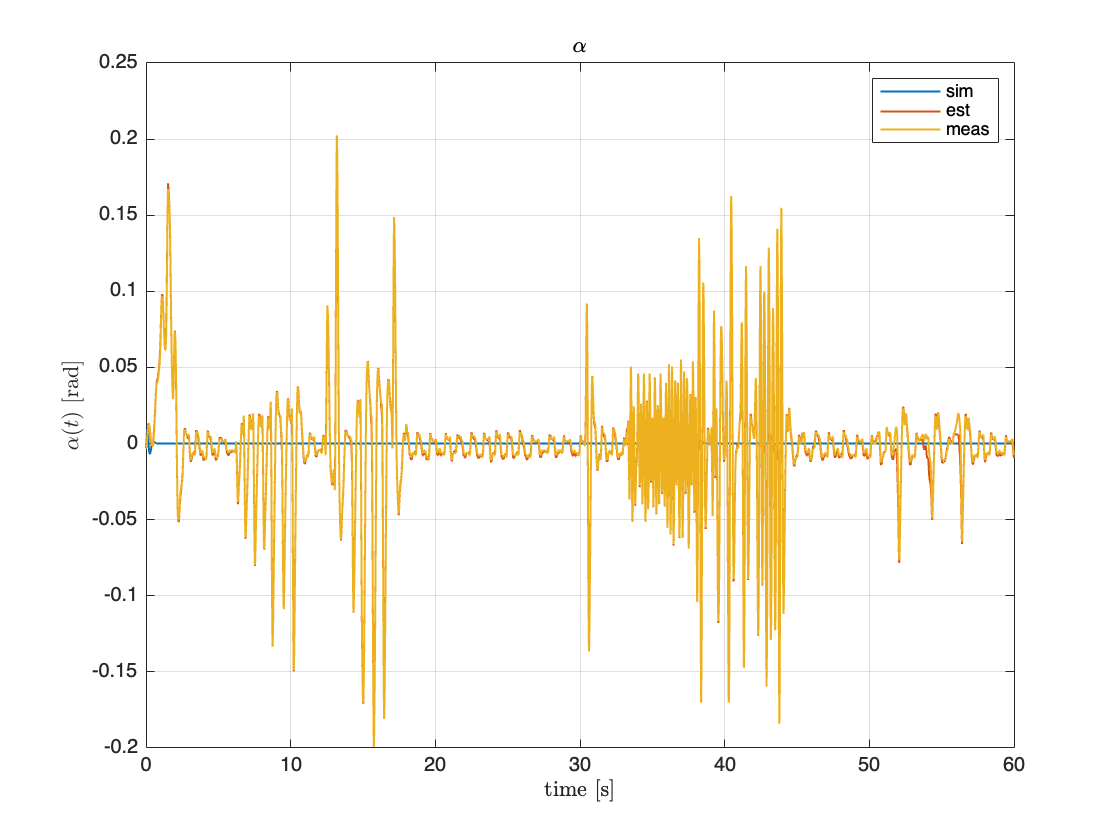

% plot alpha - alpha_est
figure,plot(Time_vec_sim(1:N_sim),ysim(2,:),Time_vec(1:N_sim),xhat(2,1:N_sim),Time_vec(1:N_sim),ymeas(2,1:N_sim),LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('sim','est','meas')
xlabel('time [s]','Interpreter','latex')
ylabel("$\alpha (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

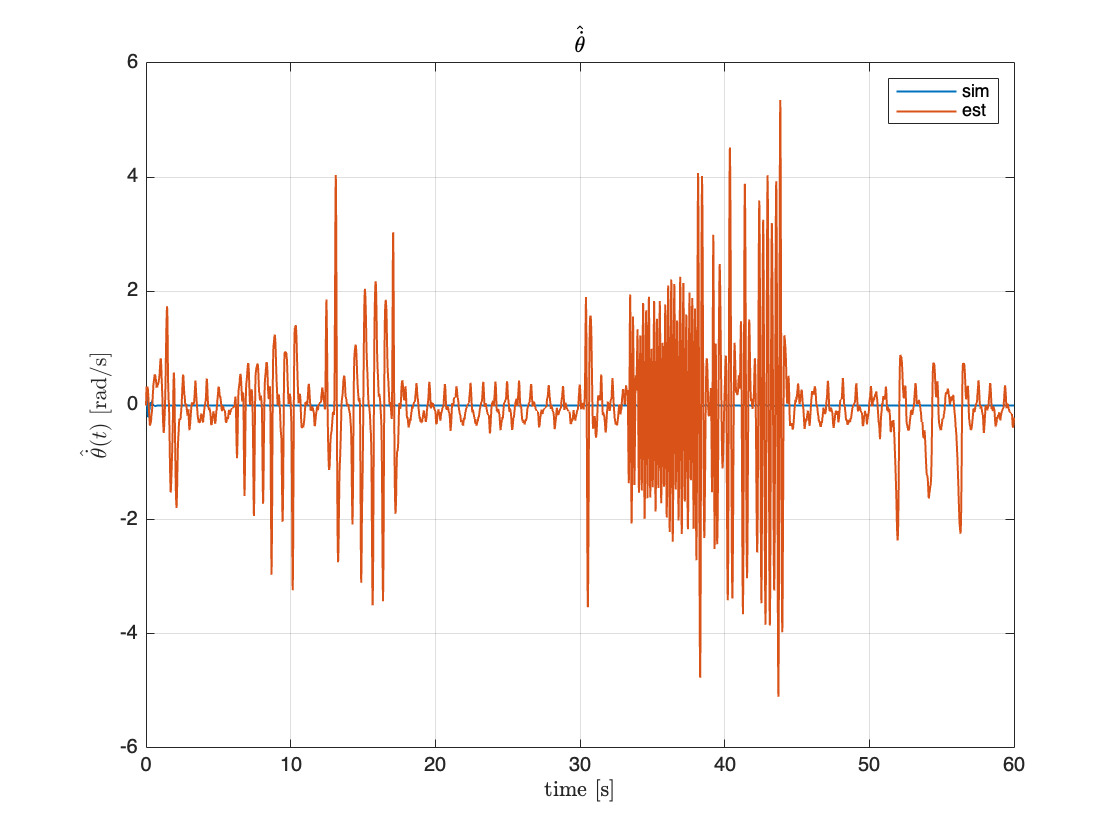

% plot theta_dot_est 
figure,plot(Time_vec_sim,ysim(3,:),Time_vec(1:N_sim),xhat(3,1:N_sim),LineWidth=1)
title('$\hat{\dot{\theta}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\theta}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

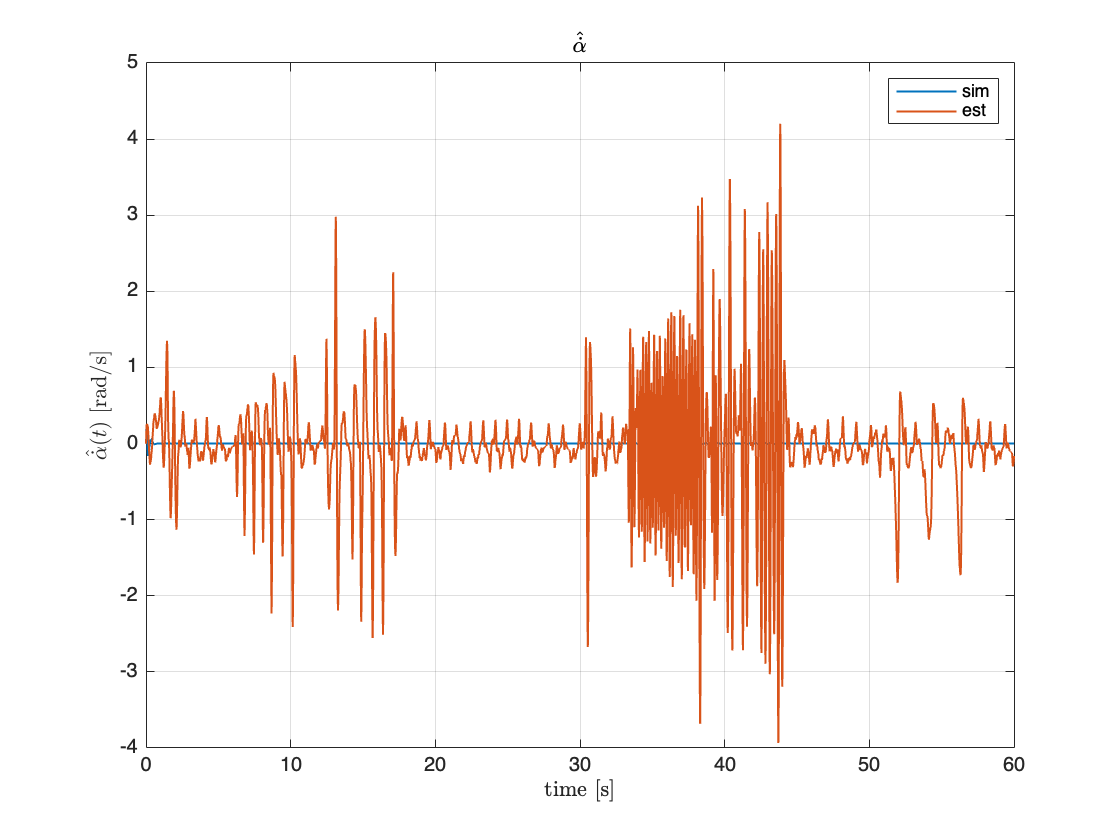


% plot alpha_dot_est
figure,plot(Time_vec_sim(1:N_sim),ysim(4,:),Time_vec(1:N_sim),xhat(4,1:N_sim),LineWidth=1)
title('$\hat{\dot{\alpha}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\alpha}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

#### With Derivatives (maybe this experiment must be done again)

### With KF (missing)

back to index

### Tracking

back to index

#### With Observer

back to index

[Time_vec,uin,theta_ref,ysim,xhat,ymeas,z0,N] = experimental_data_processing(203);
z0

z0 =          0
   -0.0153
         0
         0


Time_vec(end)

ans = 74.4020

[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim] = sim_data_processing(203);
z0_sim

z0_sim =          0
   -0.0153
         0
         0


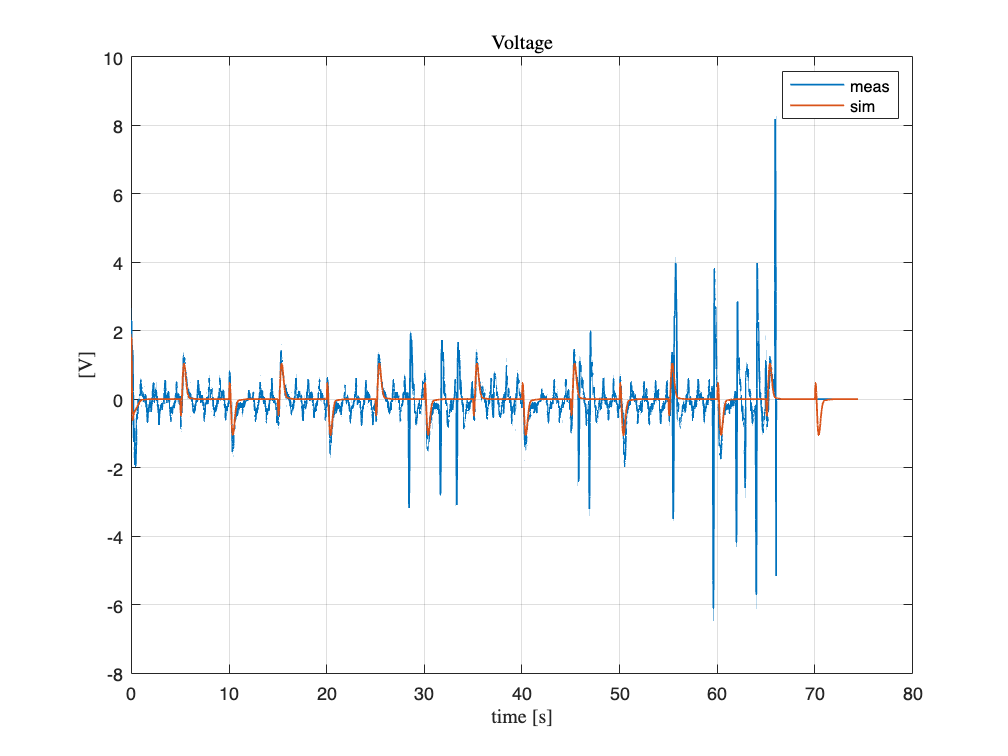

% plot the voltage signal
figure,plot(Time_vec,uin,Time_vec,uin_sim(1:N),LineWidth=1);
legend('meas','sim')
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')
grid on

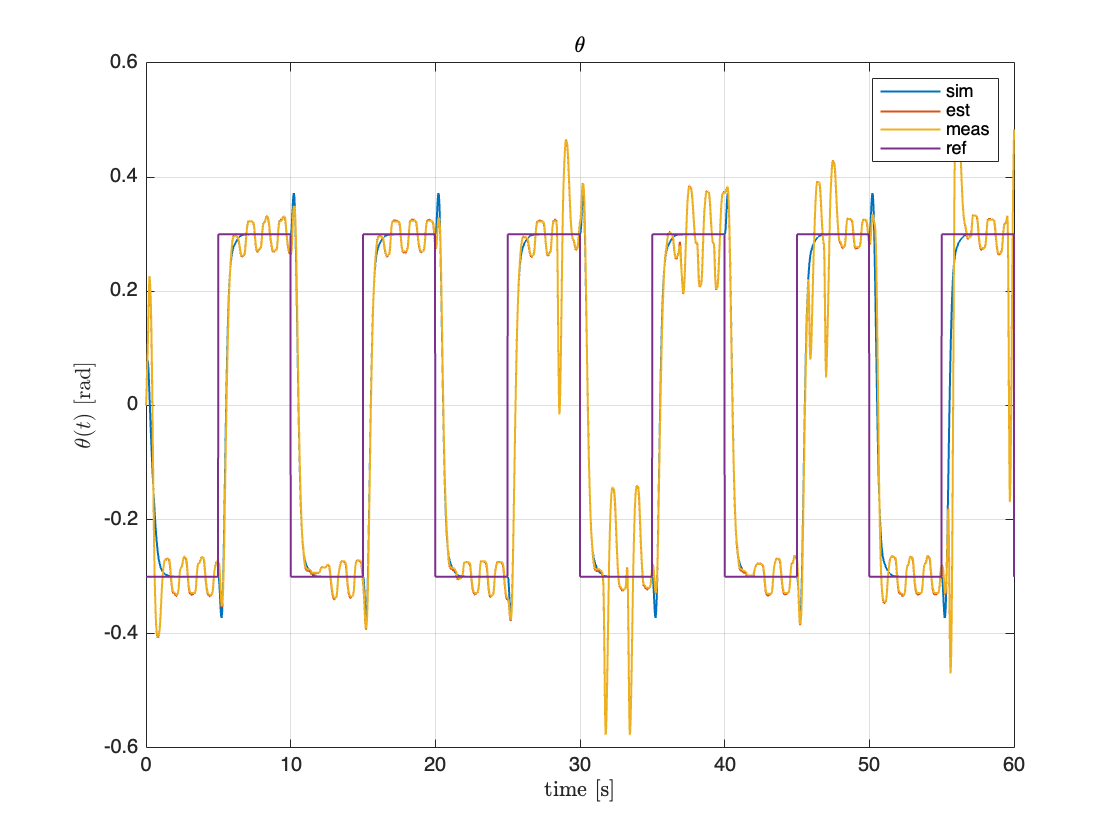

% plot theta - theta_est - theta_ref 
figure,plot(Time_vec,ysim(1,1:N),Time_vec,xhat(1,:),Time_vec,ymeas(1,:),Time_vec,theta_ref,LineWidth=1)
title('$\theta$','Interpreter','latex')
legend('sim','est','meas','ref')
xlabel('time [s]','Interpreter','latex')
ylabel("$\theta (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

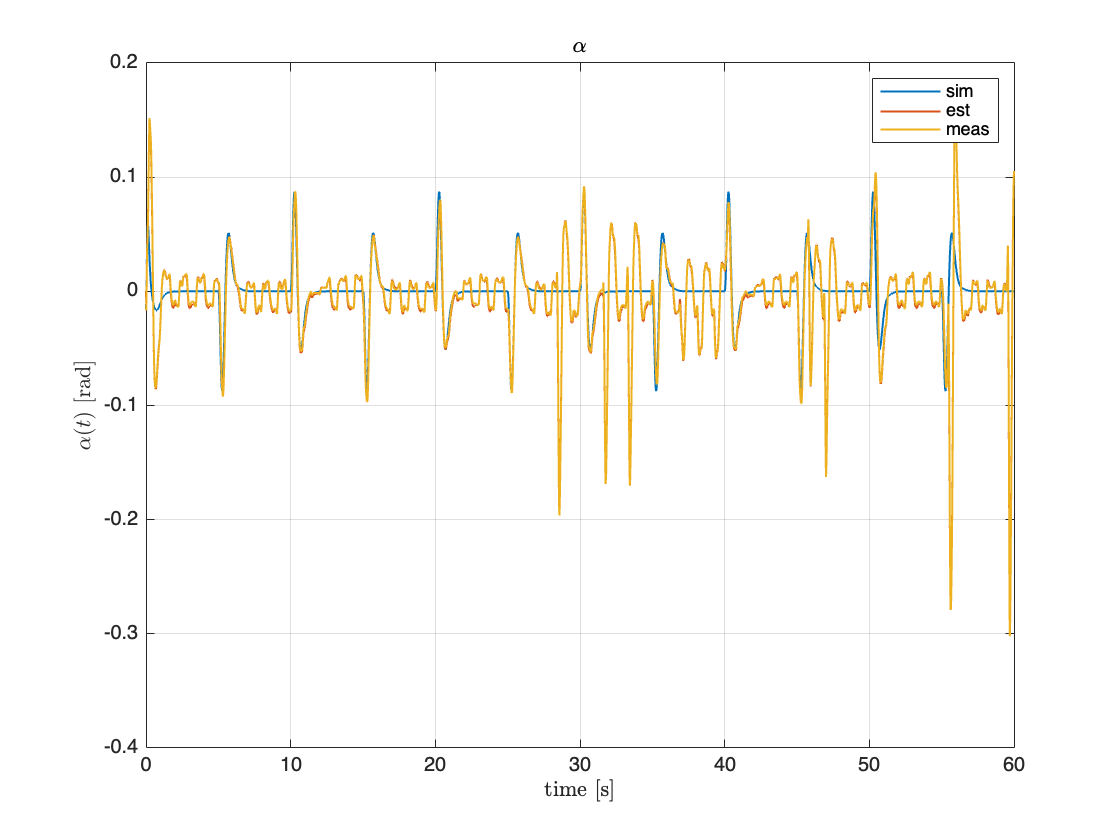

% plot alpha - alpha_est
figure,plot(Time_vec,ysim(2,1:N),Time_vec,xhat(2,:),Time_vec,ymeas(2,:),LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('sim','est','meas')
xlabel('time [s]','Interpreter','latex')
ylabel("$\alpha (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

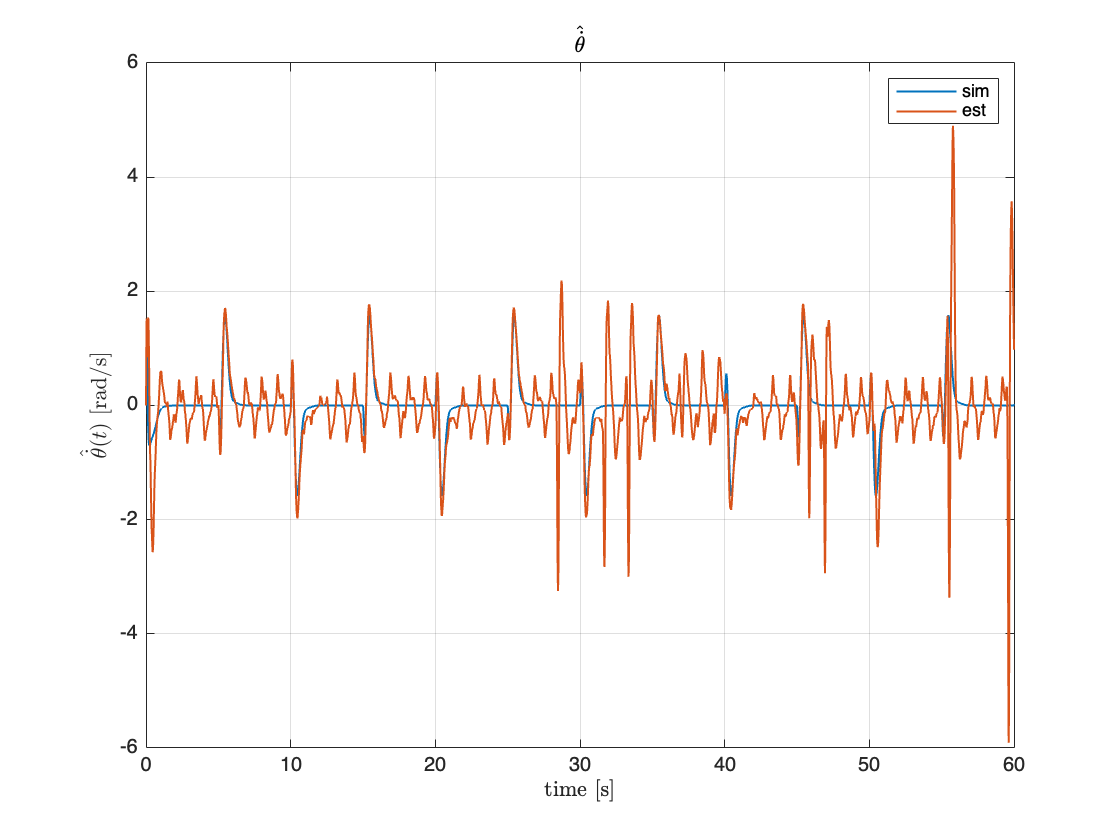


% plot theta_dot_est 
figure,plot(Time_vec,ysim(3,1:N),Time_vec,xhat(3,:),LineWidth=1)
title('$\hat{\dot{\theta}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\theta}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

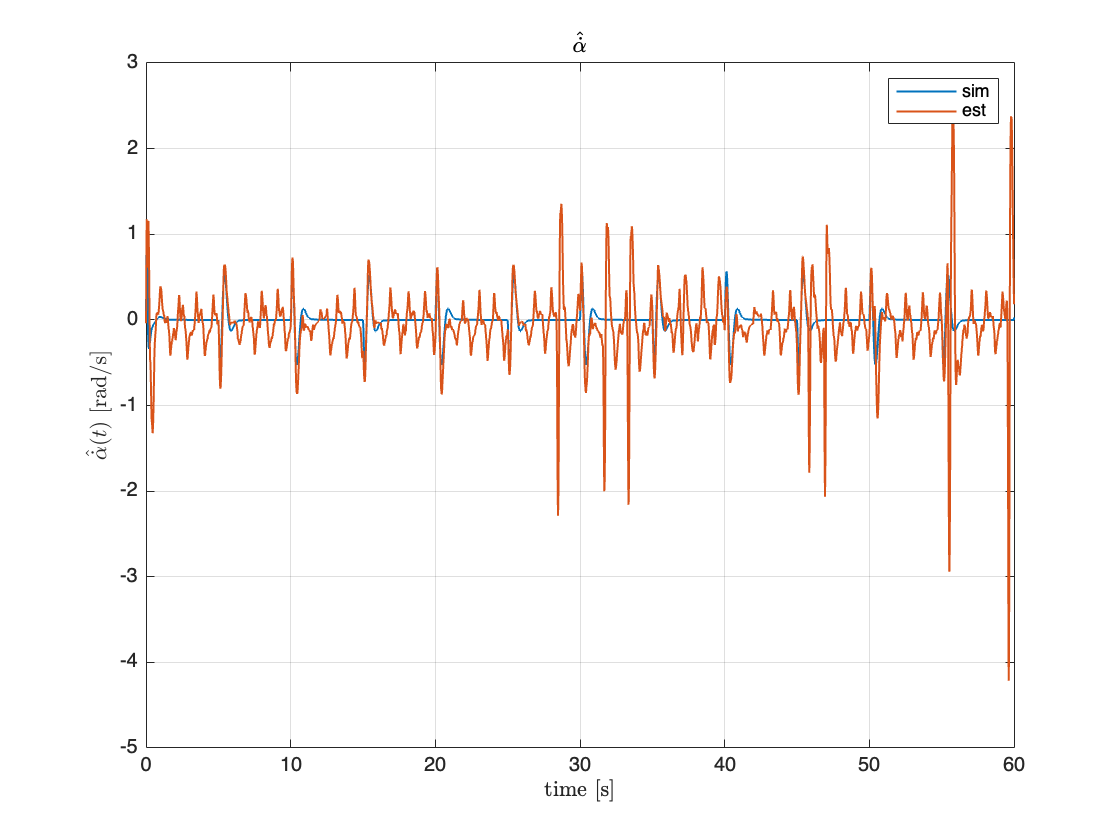

% plot alpha_dot_est
figure,plot(Time_vec,ysim(4,1:N),Time_vec,xhat(4,:),LineWidth=1)
title('$\hat{\dot{\alpha}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\alpha}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

#### With KF

back to index

[Time_vec,uin,theta_ref,ysim,xhat,ymeas,z0,N] = experimental_data_processing(212);
z0

z0 =     0.0015
    0.0092
         0
         0


Time_vec(end)

ans = 83.0330

[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim] = sim_data_processing(212);
z0_sim

z0_sim =     0.0015
    0.0092
         0
         0


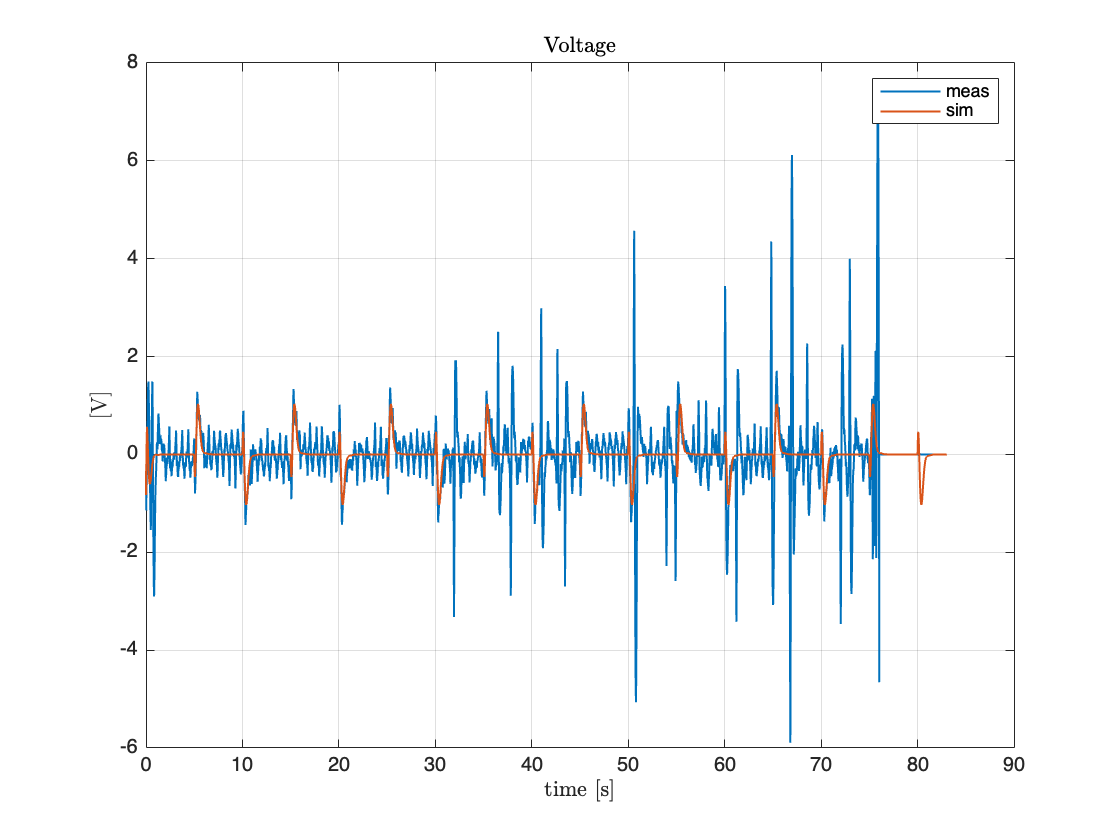

% plot the voltage signal
figure,plot(Time_vec,uin,Time_vec,uin_sim(1:N),LineWidth=1);
legend('meas','sim')
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')
grid on

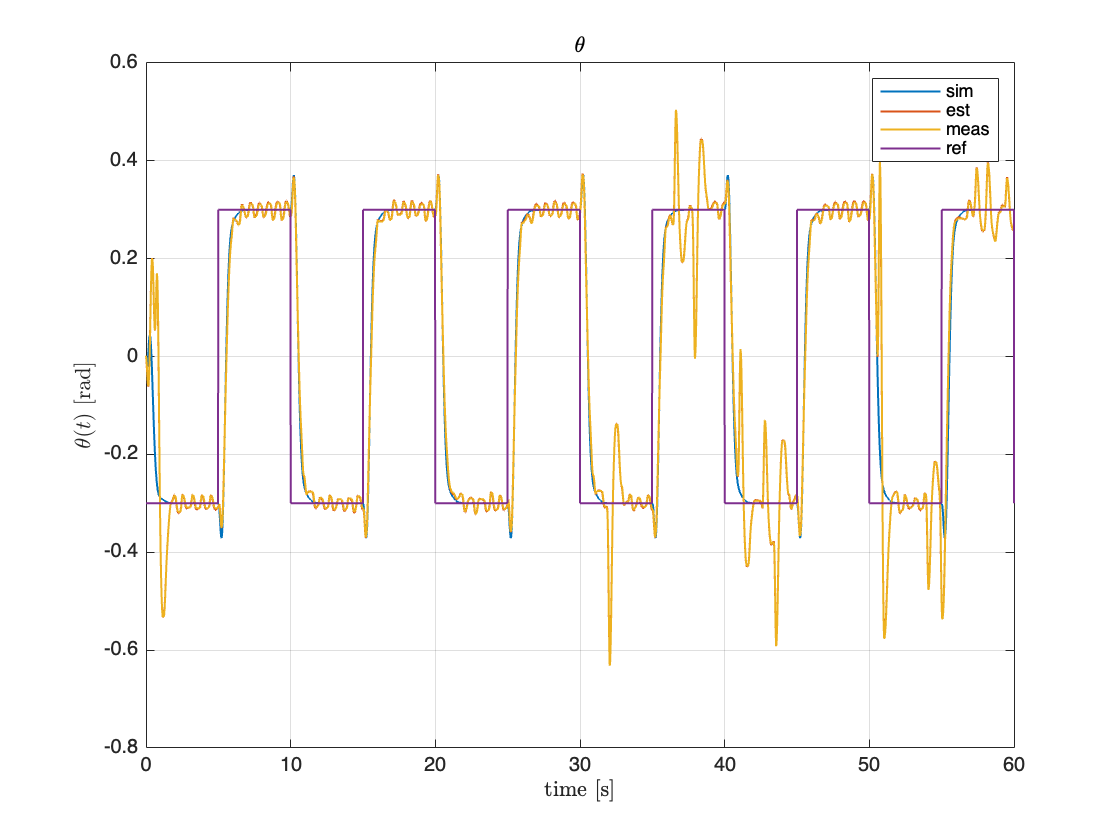

% plot theta - theta_est - theta_ref 
figure,plot(Time_vec,ysim(1,1:N),Time_vec,xhat(1,:),Time_vec,ymeas(1,:),Time_vec,theta_ref,LineWidth=1)
title('$\theta$','Interpreter','latex')
legend('sim','est','meas','ref')
xlabel('time [s]','Interpreter','latex')
ylabel("$\theta (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

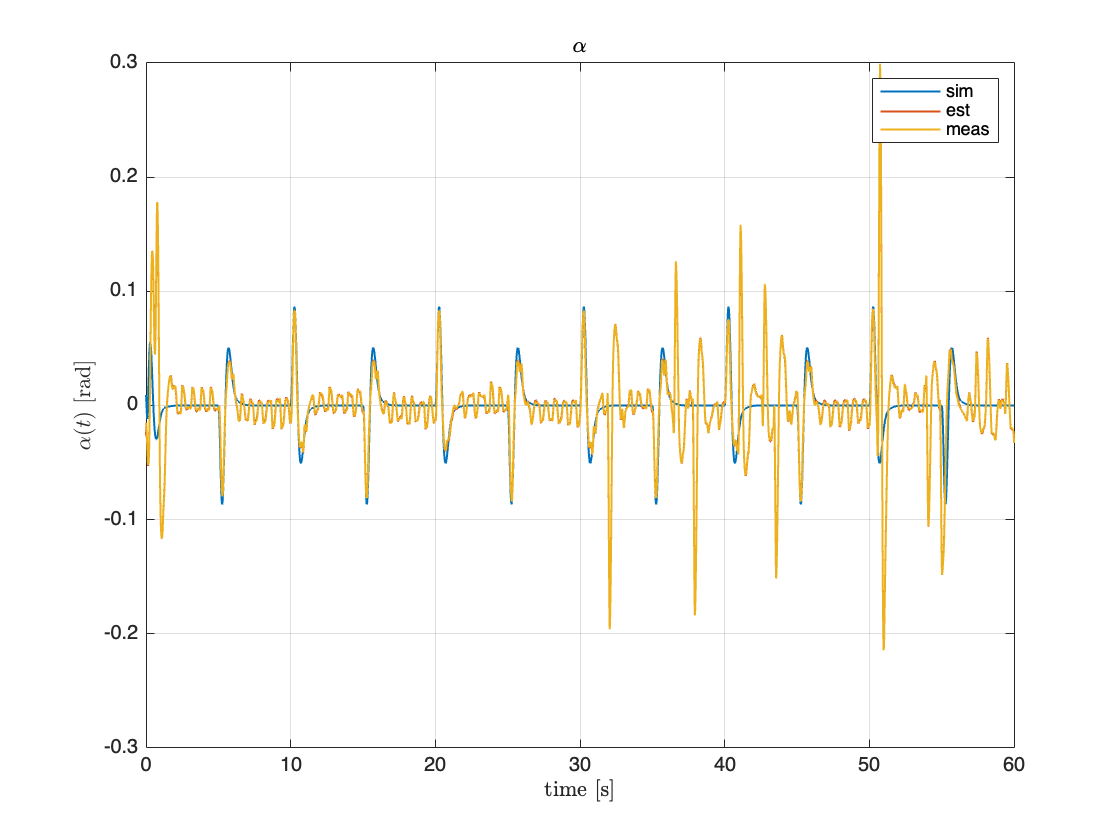

% plot alpha - alpha_est
ymeas(2,:) = ymeas(2,:) - mean(ymeas(2,1:30000));
xhat(2,:) = xhat(2,:) - mean(xhat(2,1:30000));
figure,plot(Time_vec,ysim(2,1:N),Time_vec,xhat(2,:),Time_vec,ymeas(2,:),LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('sim','est','meas')
xlabel('time [s]','Interpreter','latex')
ylabel("$\alpha (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

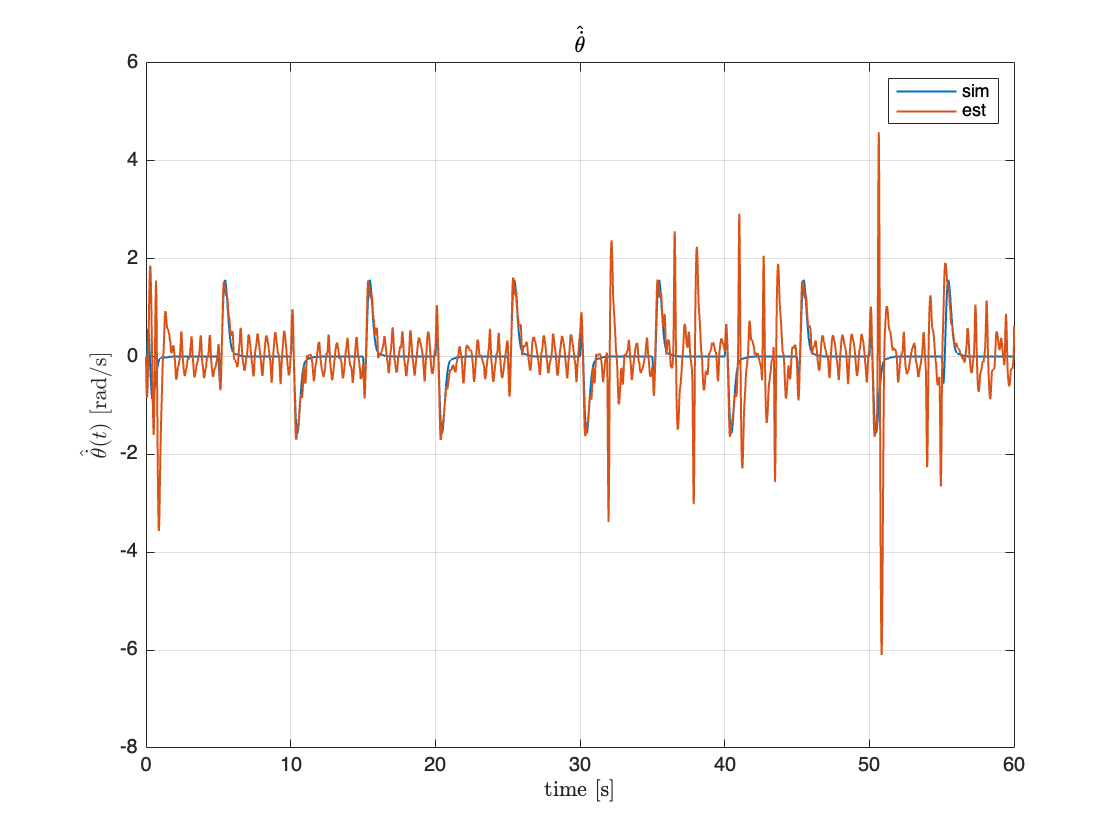


% plot theta_dot_est 
figure,plot(Time_vec,ysim(3,1:N),Time_vec,xhat(3,:),LineWidth=1)
title('$\hat{\dot{\theta}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\theta}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

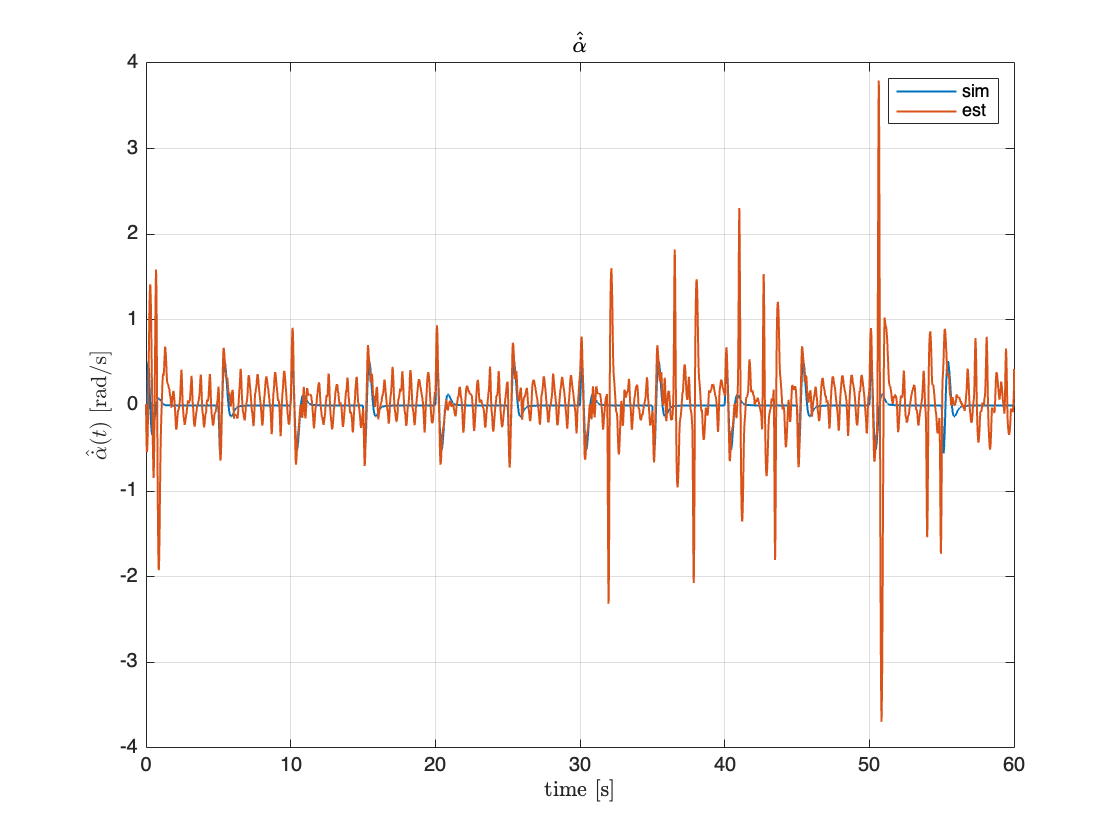

% plot alpha_dot_est
figure,plot(Time_vec,ysim(4,1:N),Time_vec,xhat(4,:),LineWidth=1)
title('$\hat{\dot{\alpha}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\alpha}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

## LQ Control

### Stabilization

#### With Observer

back to index

[Time_vec,uin,theta_ref,ysim,xhat,ymeas,z0,N] = experimental_data_processing(216);
z0 

z0 =          0
   -0.0245
         0
         0


Time_vec(end)

ans = 56.9880

[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim] = sim_data_processing(216);
z0_sim

z0_sim =          0
   -0.0245
         0
         0


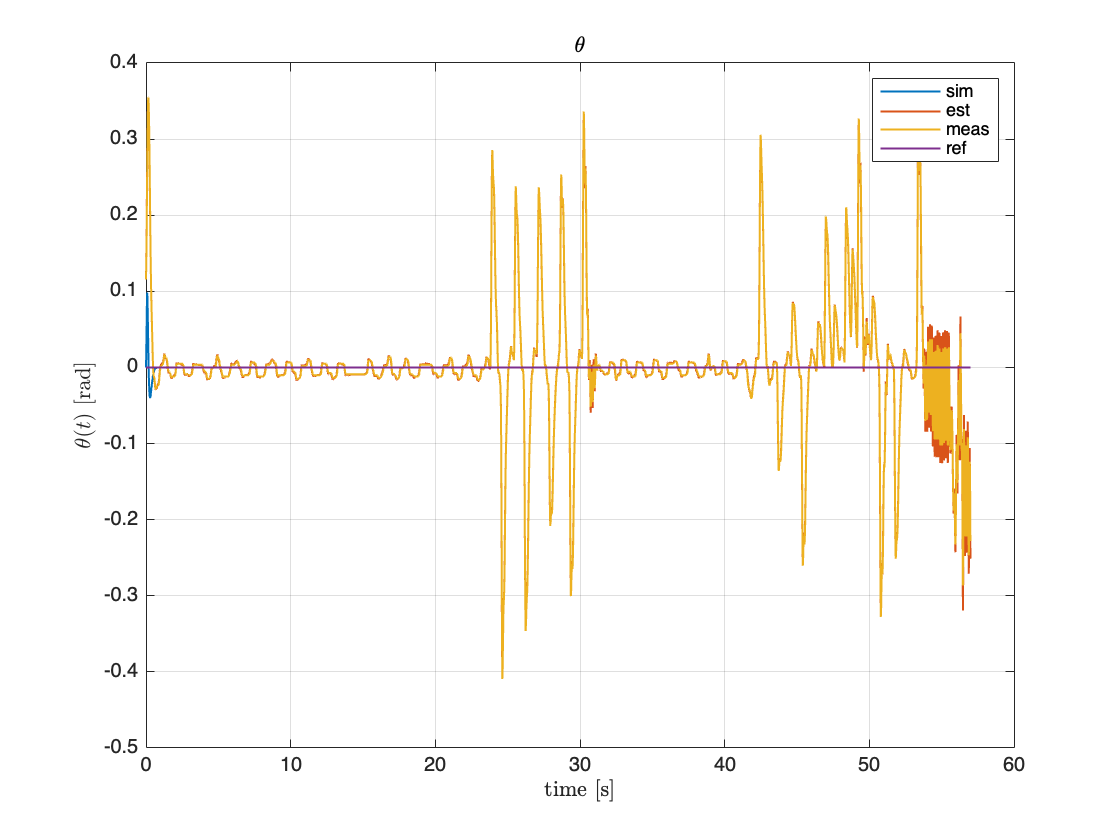


% plot the voltage signal
figure,plot(Time_vec,uin,Time_vec,uin_sim(1:N),LineWidth=1);
legend('meas','sim')
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')
grid on
% plot theta - theta_est - theta_ref 

ymeas(1,:) = ymeas(1,:) - mean(ymeas(1,:));
xhat(1,:) = xhat(1,:) - mean(xhat(1,:));
figure,plot(Time_vec,ysim(1,1:N),Time_vec,xhat(1,:),Time_vec,ymeas(1,:),Time_vec,theta_ref,LineWidth=1)
title('$\theta$','Interpreter','latex')
legend('sim','est','meas','ref')
xlabel('time [s]','Interpreter','latex')
ylabel("$\theta (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

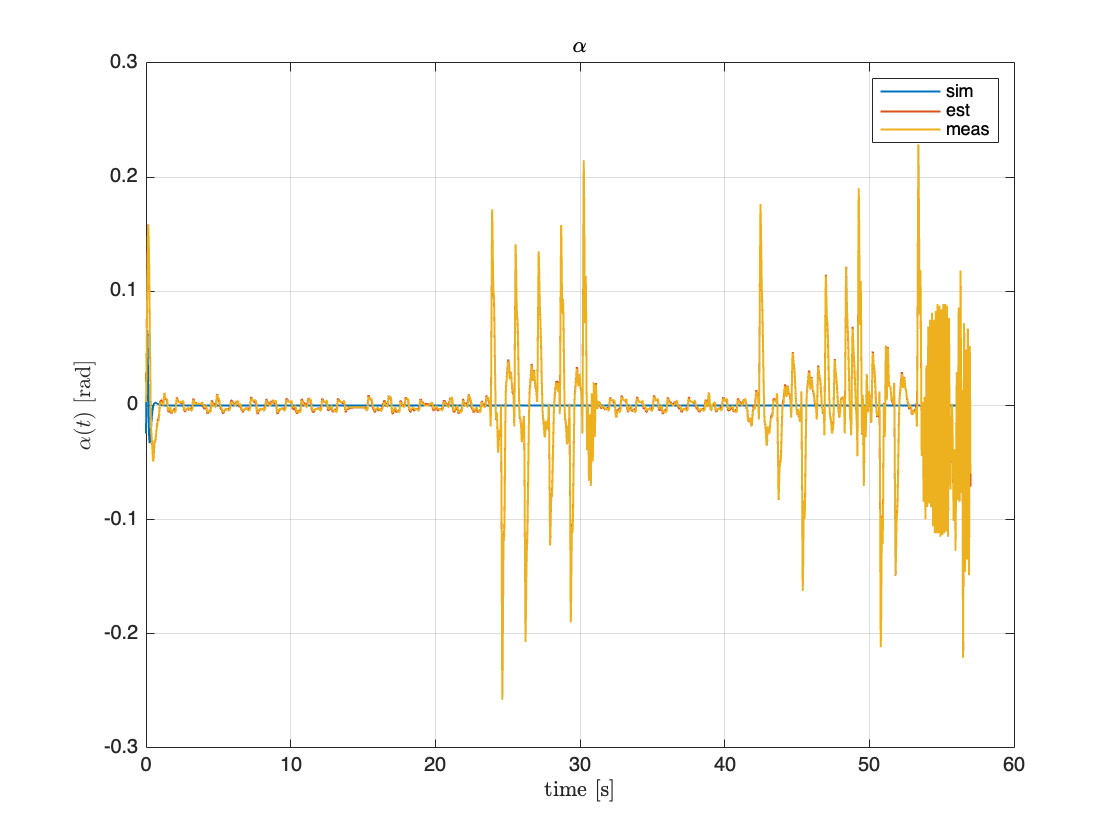

% plot alpha - alpha_est
ymeas(2,:) = ymeas(2,:) - mean(ymeas(2,:));
xhat(2,:) = xhat(2,:) - mean(xhat(2,:));
figure,plot(Time_vec,ysim(2,1:N),Time_vec,xhat(2,:),Time_vec,ymeas(2,:),LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('sim','est','meas')
xlabel('time [s]','Interpreter','latex')
ylabel("$\alpha (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

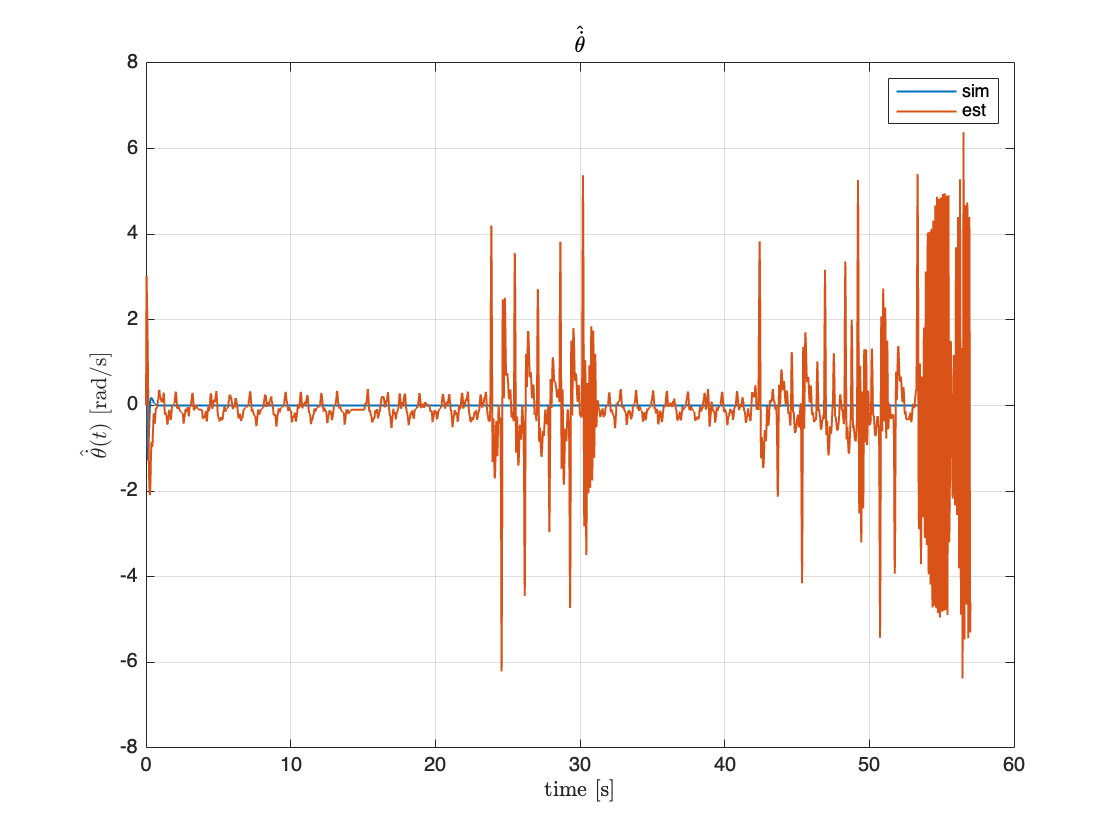


% plot theta_dot_est 
figure,plot(Time_vec,ysim(3,1:N),Time_vec,xhat(3,:),LineWidth=1)
title('$\hat{\dot{\theta}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\theta}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

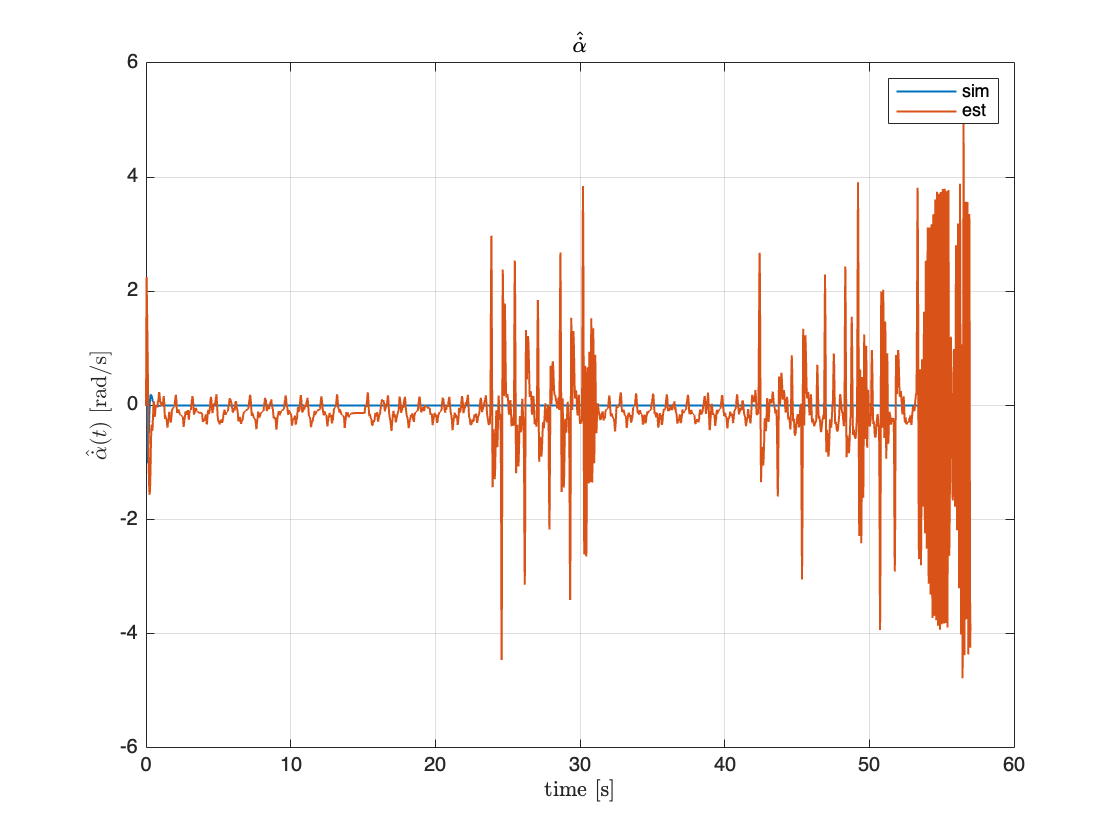

% plot alpha_dot_est
figure,plot(Time_vec,ysim(4,1:N),Time_vec,xhat(4,:),LineWidth=1)
title('$\hat{\dot{\alpha}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\alpha}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

#### With KF

back to index

[Time_vec,uin,theta_ref,ysim,xhat,ymeas,z0,N] = experimental_data_processing(213);
z0

z0 =          0
    0.0215
         0
         0


Time_vec(end)

ans = 90.4360

[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim] = sim_data_processing(213);
z0_sim

z0_sim =          0
    0.0215
         0
         0


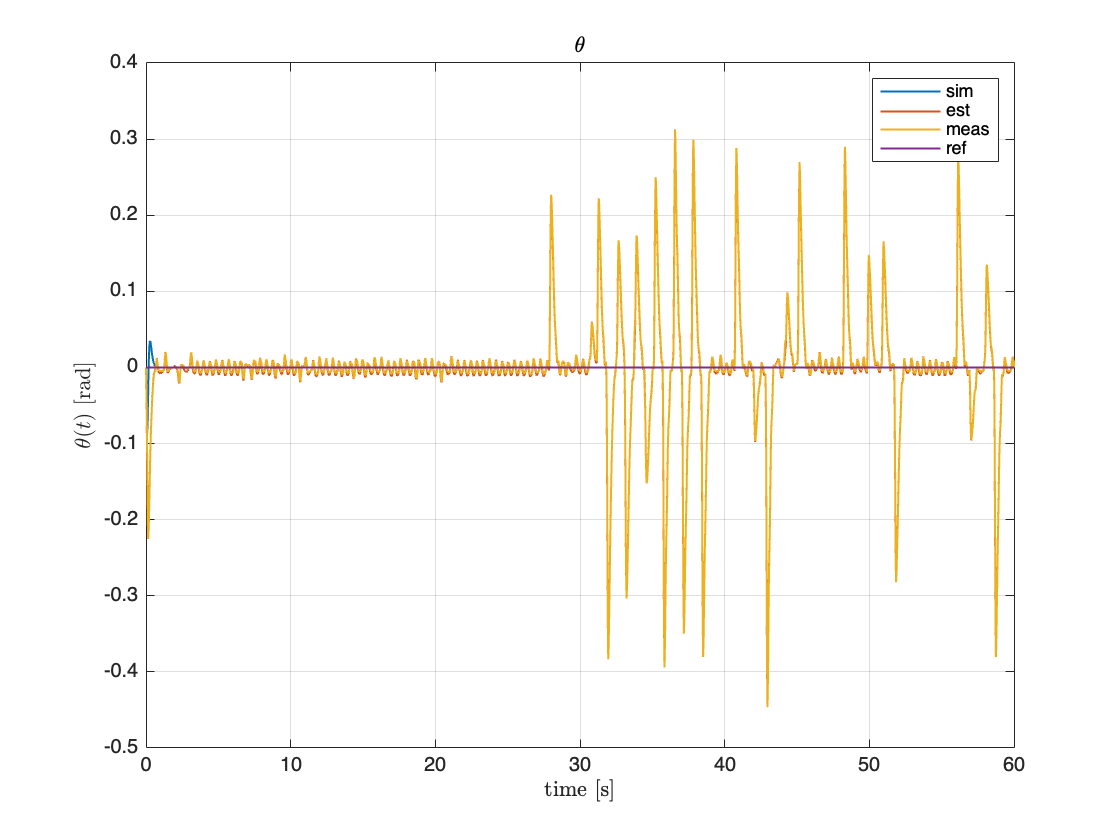


% plot the voltage signal
figure,plot(Time_vec,uin,Time_vec,uin_sim(1:N),LineWidth=1);
legend('meas','sim')
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')
grid on
% plot theta - theta_est - theta_ref 
figure,plot(Time_vec,ysim(1,1:N),Time_vec,xhat(1,:),Time_vec,ymeas(1,:),Time_vec,theta_ref,LineWidth=1)
title('$\theta$','Interpreter','latex')
legend('sim','est','meas','ref')
xlabel('time [s]','Interpreter','latex')
ylabel("$\theta (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

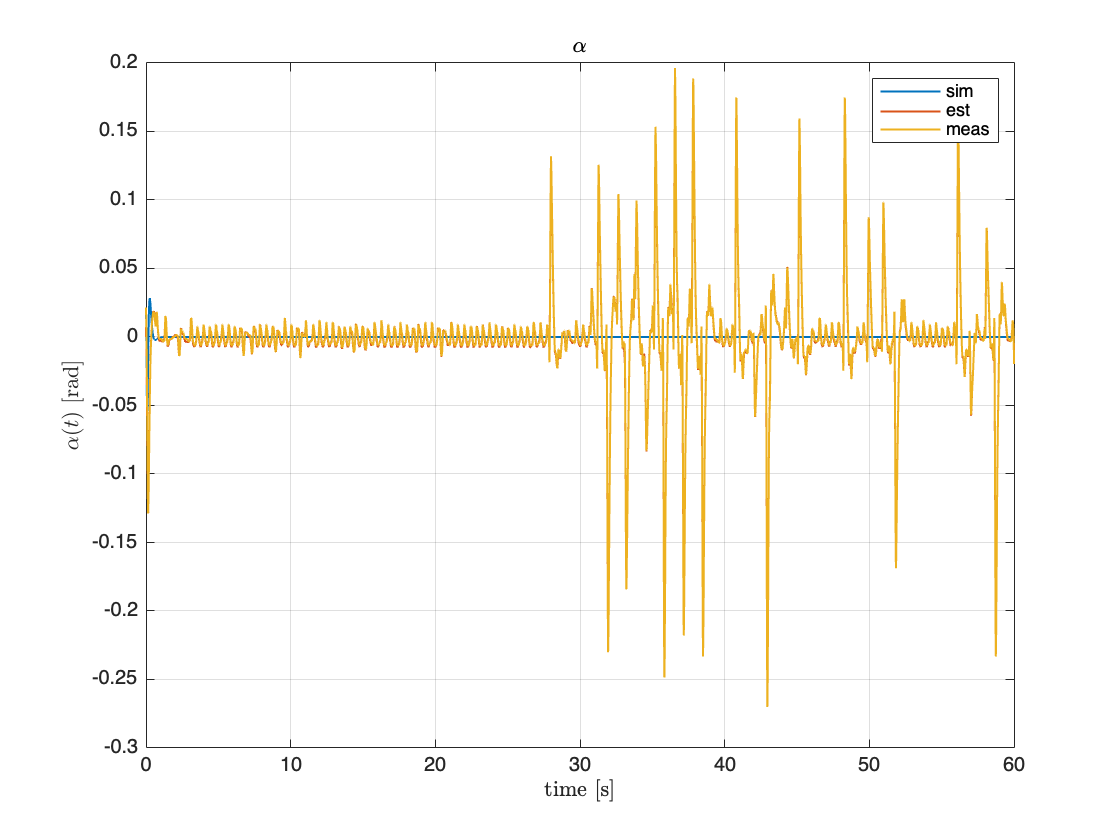

% plot alpha - alpha_est
figure,plot(Time_vec,ysim(2,1:N),Time_vec,xhat(2,:),Time_vec,ymeas(2,:),LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('sim','est','meas')
xlabel('time [s]','Interpreter','latex')
ylabel("$\alpha (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

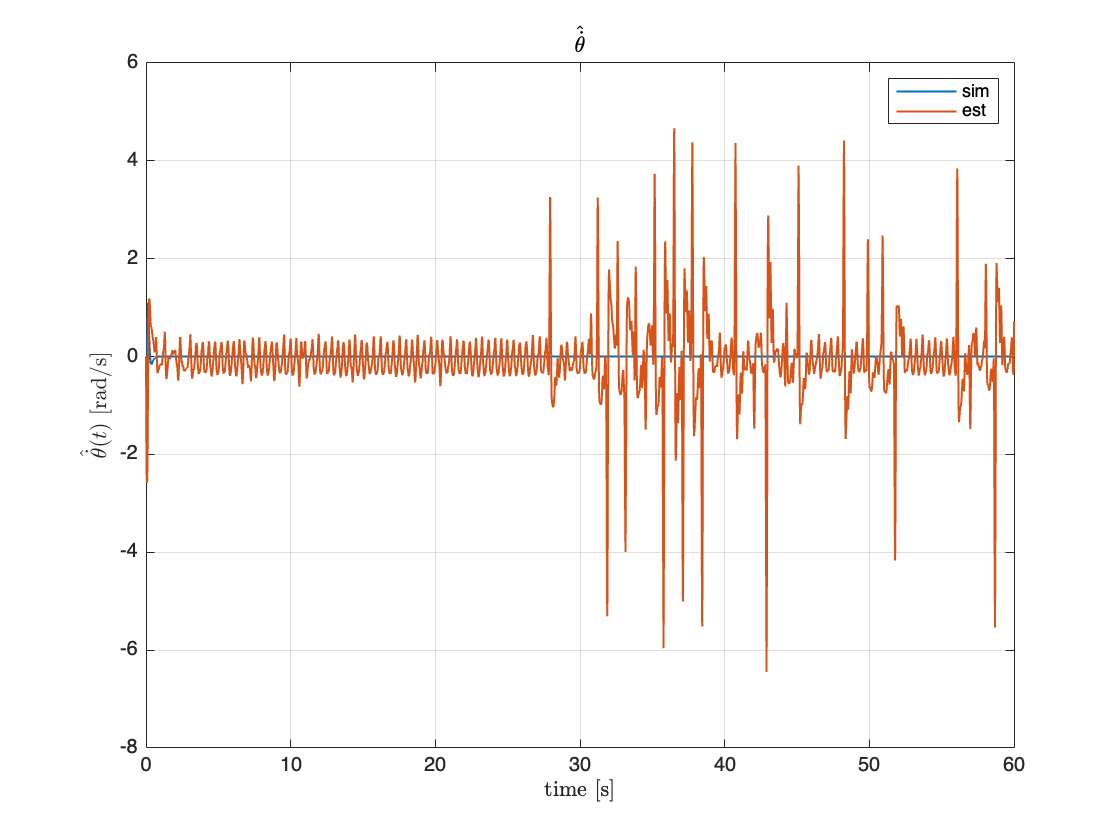


% plot theta_dot_est 
figure,plot(Time_vec,ysim(3,1:N),Time_vec,xhat(3,:),LineWidth=1)
title('$\hat{\dot{\theta}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\theta}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

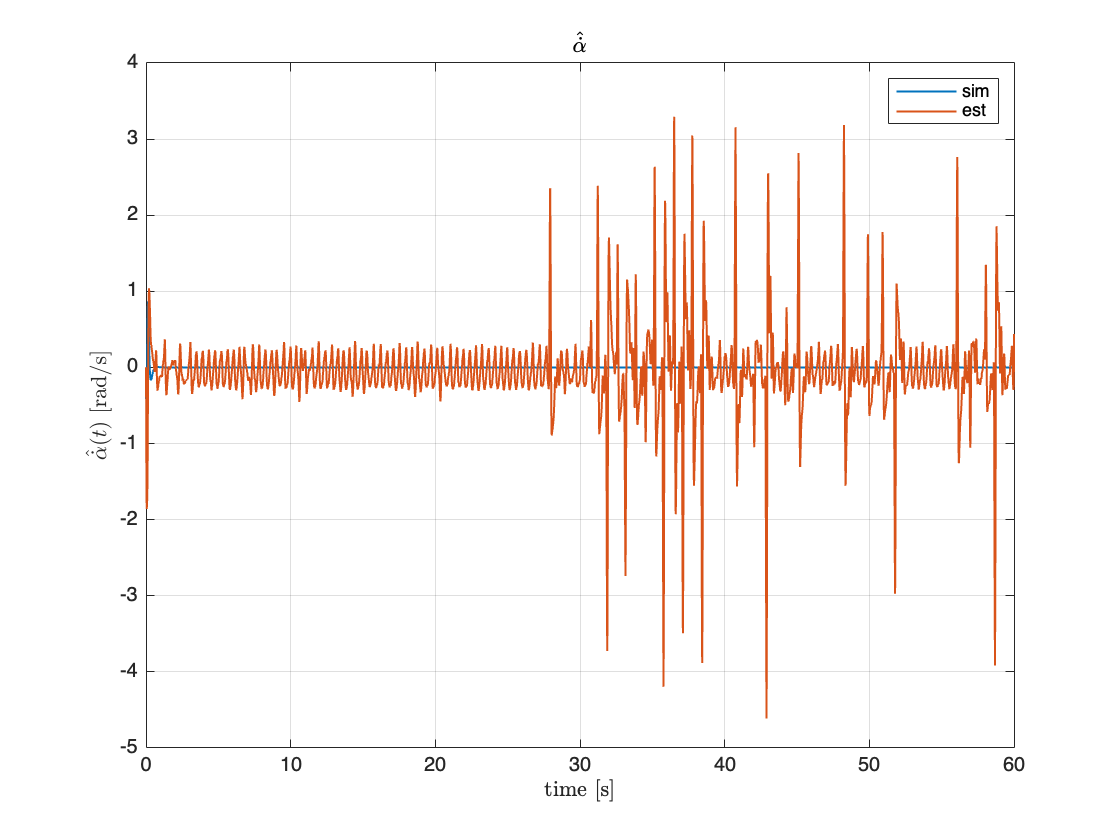

% plot alpha_dot_est
figure,plot(Time_vec,ysim(4,1:N),Time_vec,xhat(4,:),LineWidth=1)
title('$\hat{\dot{\alpha}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\alpha}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

### Tracking

### Observer

back to index

[Time_vec,uin,theta_ref,ysim,xhat,ymeas,z0,N] = experimental_data_processing(215);
z0

z0 =          0
    0.0138
         0
         0


Time_vec(end)

ans = 102.7340

[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim] = sim_data_processing(215);
z0_sim

z0_sim =          0
    0.0138
         0
         0


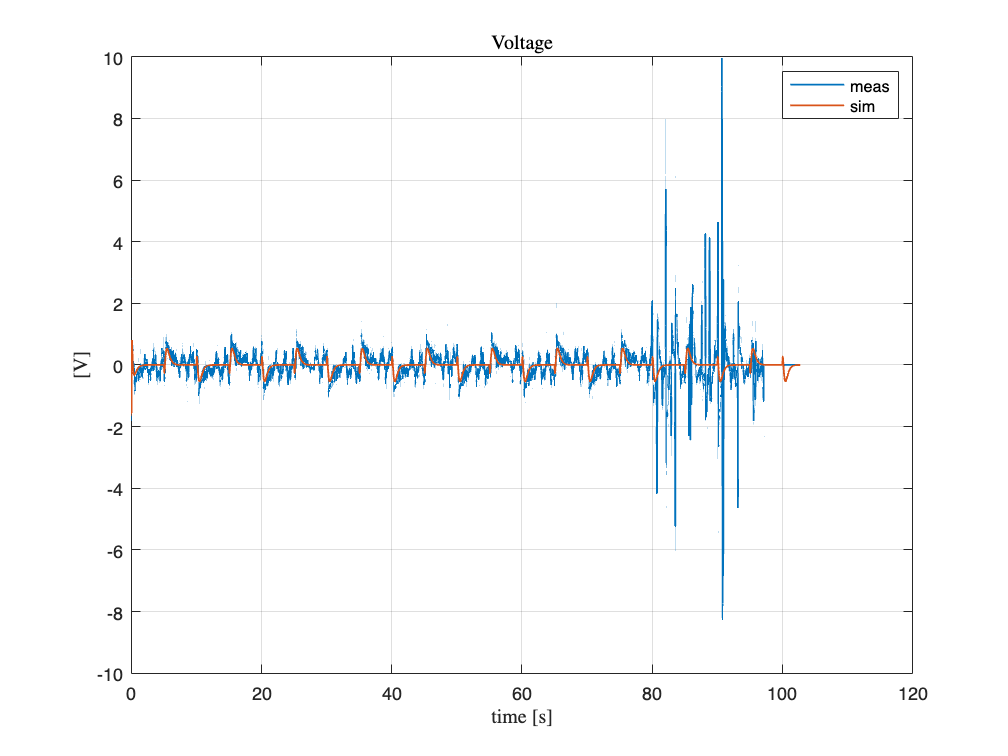


% plot the voltage signal
figure,plot(Time_vec,uin,Time_vec,uin_sim(1:N),LineWidth=1);
legend('meas','sim')
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')
grid on

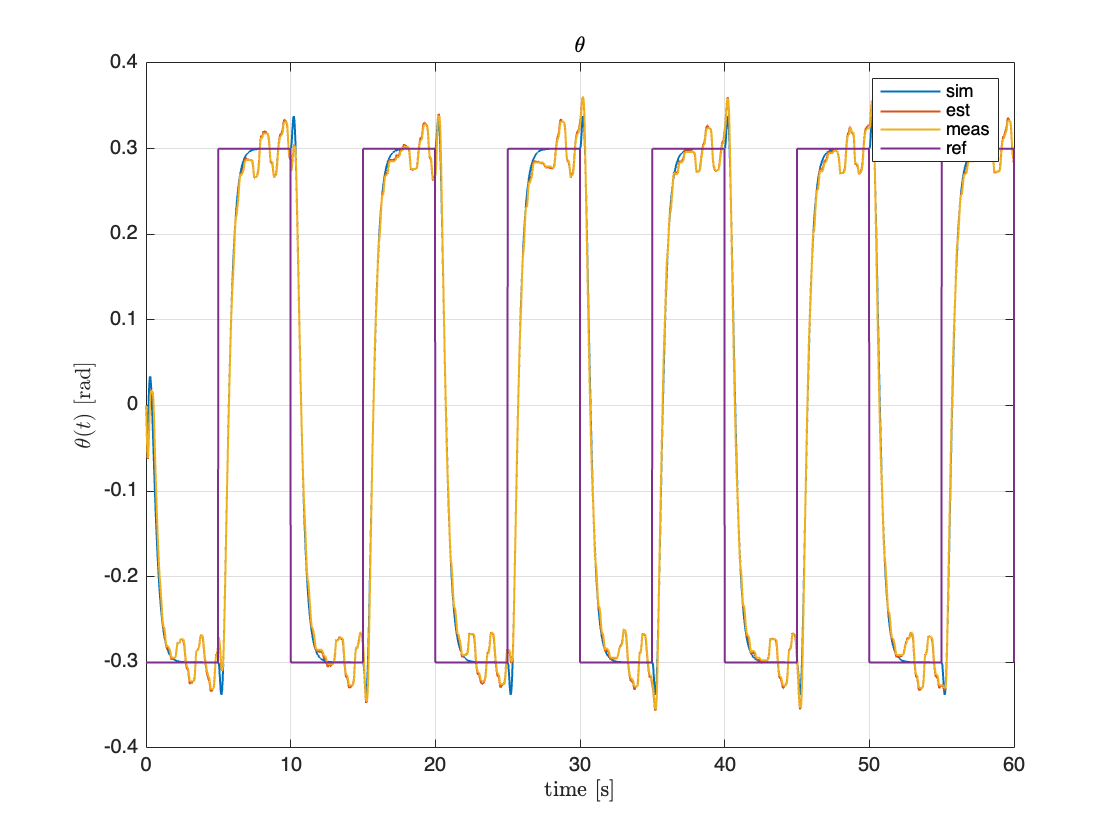

% plot theta - theta_est - theta_ref 
figure,plot(Time_vec,ysim(1,1:N),Time_vec,xhat(1,:),Time_vec,ymeas(1,:),Time_vec,theta_ref,LineWidth=1)
title('$\theta$','Interpreter','latex')
legend('sim','est','meas','ref')
xlabel('time [s]','Interpreter','latex')
ylabel("$\theta (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

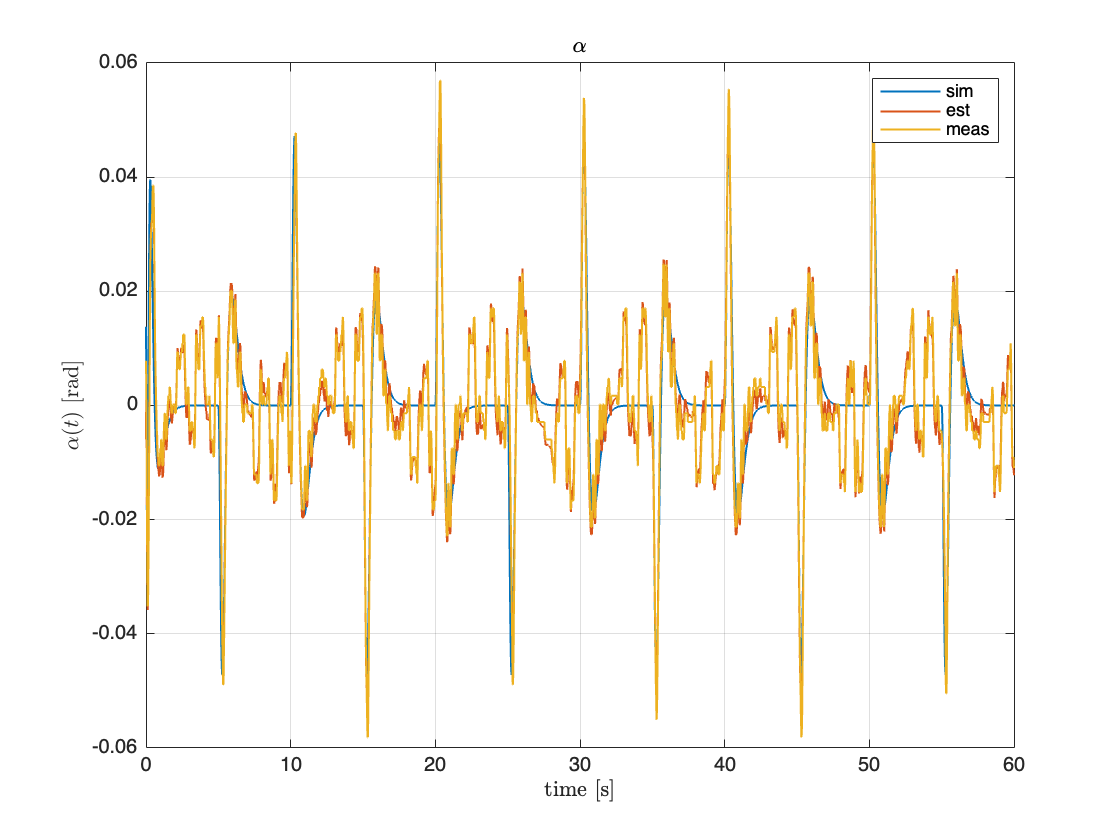

% plot alpha - alpha_est
ymeas(2,:) = ymeas(2,:) - mean(ymeas(2,1:60000));
xhat(2,:) = xhat(2,:) - mean(xhat(2,1:60000));
figure,plot(Time_vec,ysim(2,1:N),Time_vec,xhat(2,:),Time_vec,ymeas(2,:),LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('sim','est','meas')
xlabel('time [s]','Interpreter','latex')
ylabel("$\alpha (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

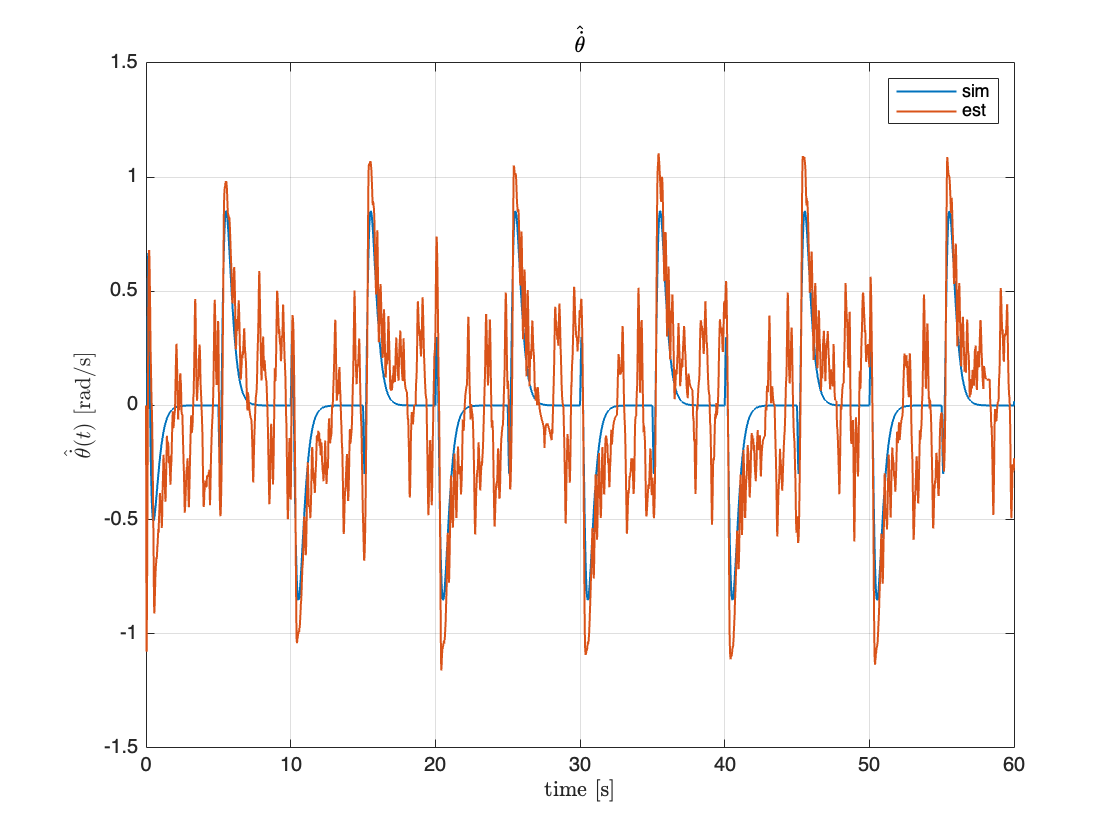


% plot theta_dot_est 
figure,plot(Time_vec,ysim(3,1:N),Time_vec,xhat(3,:),LineWidth=1)
title('$\hat{\dot{\theta}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\theta}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

#### With KF

back to index

[Time_vec,uin,theta_ref,ysim,xhat,ymeas,z0,N] = experimental_data_processing(214);
z0

z0 =      0
     0
     0
     0


Time_vec(end)

ans = 360.2670

[Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim] = sim_data_processing(214);
z0_sim

z0_sim =      0
     0
     0
     0


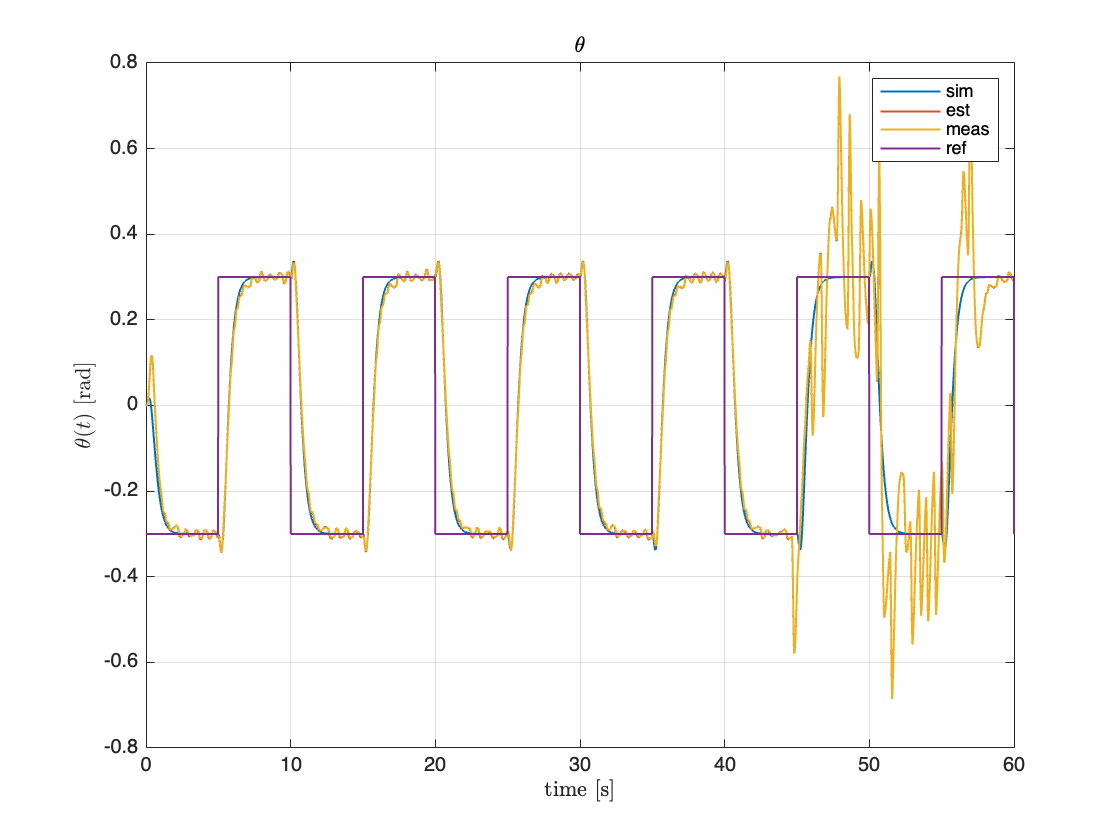

% plot the voltage signal
figure,plot(Time_vec(1:N_sim),uin(1:N_sim),Time_vec_sim(1:N_sim),uin_sim,LineWidth=1);
legend('meas','sim')
title('Voltage','Interpreter','latex')
xlabel("time [s]",'Interpreter','latex')
ylabel("[V]",'Interpreter','latex')

% plot theta - theta_est - theta_ref 
figure,plot(Time_vec_sim,ysim(1,:),Time_vec(1:N_sim),xhat(1,1:N_sim),Time_vec(1:N_sim),ymeas(1,1:N_sim),Time_vec,theta_ref,LineWidth=1)
title('$\theta$','Interpreter','latex')
legend('sim','est','meas','ref')
xlabel('time [s]','Interpreter','latex')
ylabel("$\theta (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

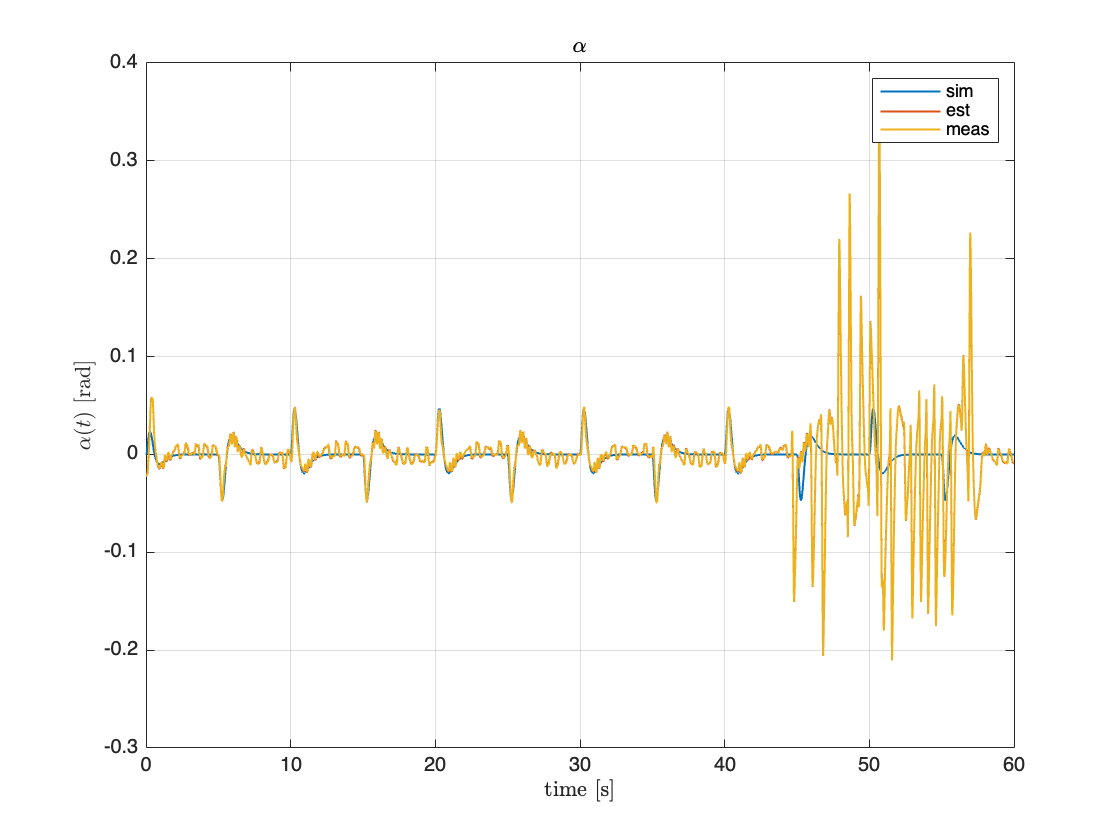

% plot alpha - alpha_est
ymeas(2,:) = ymeas(2,:) - mean(ymeas(2,1:40000));
xhat(2,:) = xhat(2,:) - mean(xhat(2,1:40000));
figure,plot(Time_vec_sim(1:N_sim),ysim(2,:),Time_vec(1:N_sim),xhat(2,1:N_sim),Time_vec(1:N_sim),ymeas(2,1:N_sim),LineWidth=1)
title('$\alpha$','Interpreter','latex')
legend('sim','est','meas')
xlabel('time [s]','Interpreter','latex')
ylabel("$\alpha (t)$ [rad]",'Interpreter','latex')
xlim([0 t_max])
grid on

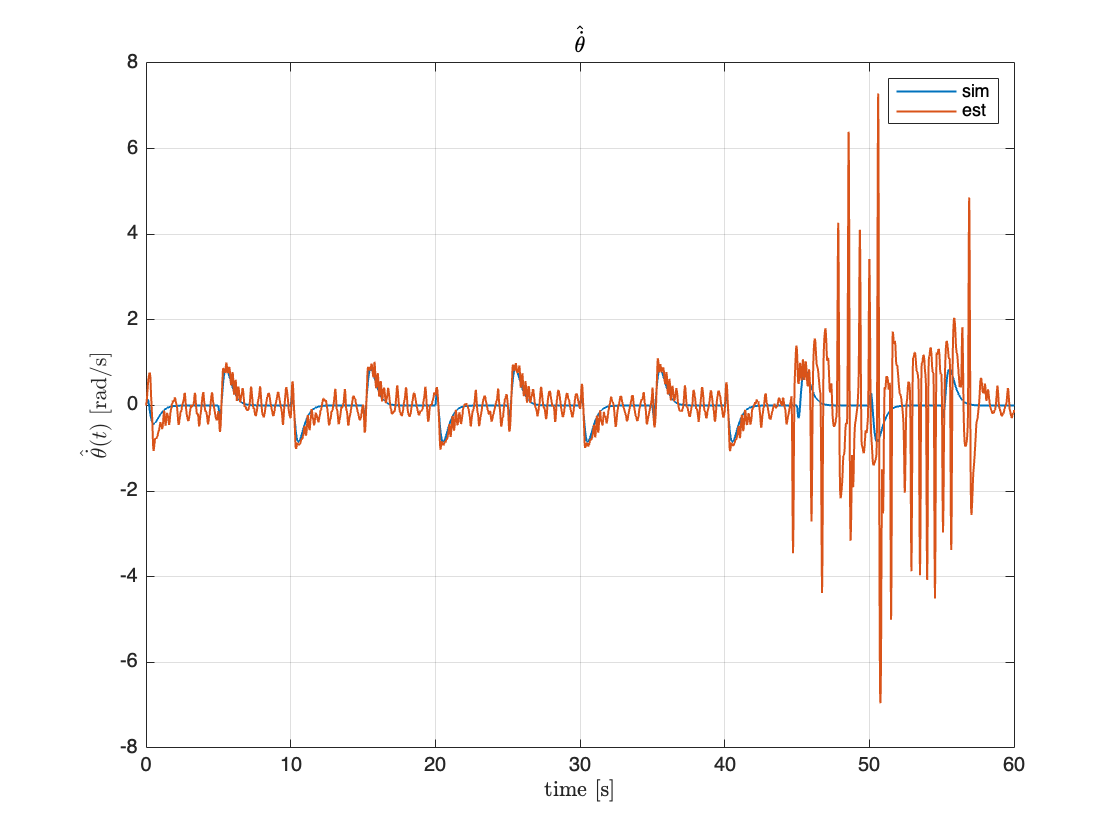

% plot theta_dot_est 
figure,plot(Time_vec_sim,ysim(3,:),Time_vec(1:N_sim),xhat(3,1:N_sim),LineWidth=1)
title('$\hat{\dot{\theta}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\theta}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])
grid on

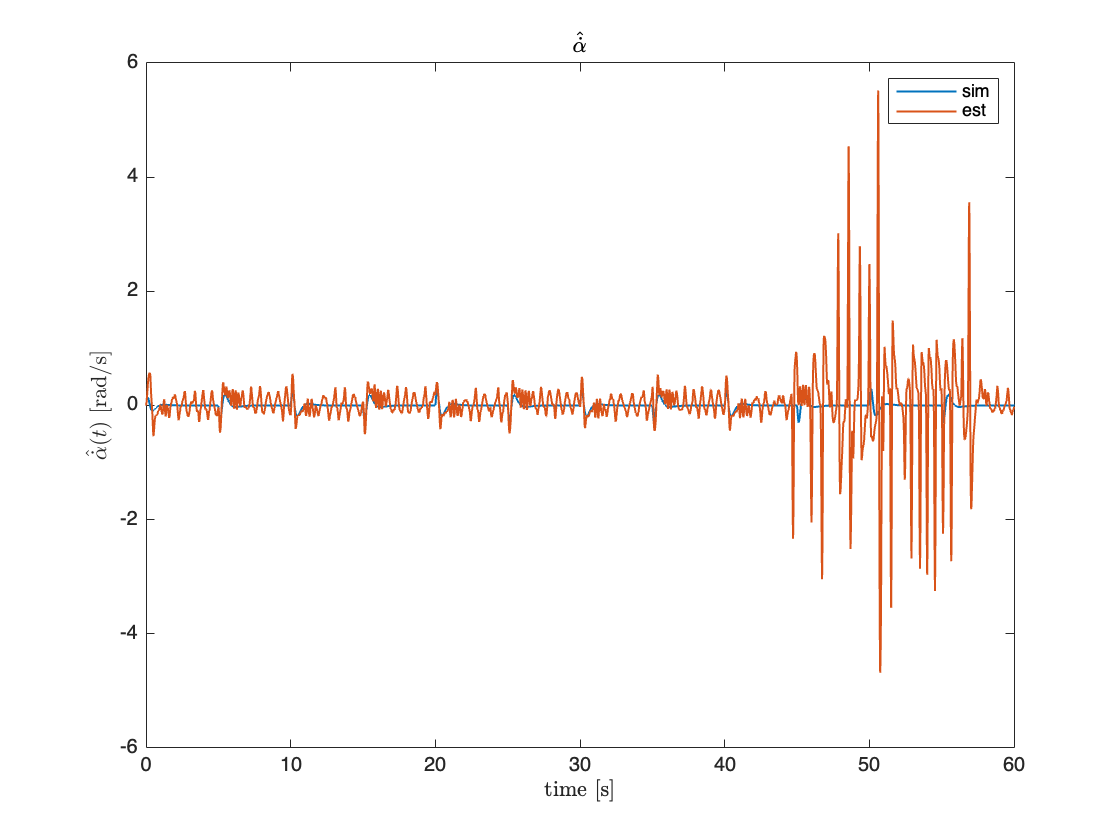


% plot alpha_dot_est
figure,plot(Time_vec_sim(1:N_sim),ysim(4,:),Time_vec(1:N_sim),xhat(4,1:N_sim),LineWidth=1)
title('$\hat{\dot{\alpha}}$','Interpreter','latex')
legend('sim','est')
xlabel('time [s]','Interpreter','latex')
ylabel("$\hat{\dot{\alpha}}(t)$ [rad/s]",'Interpreter','latex')
xlim([0 t_max])

# Auxiliary Functions

function [Time_vec,uin,theta_ref,ysim,xhat,ymeas,z0,N] = experimental_data_processing(n_exp)

train_exp = n_exp;

% want row vectors !!!
uin = cell2mat(struct2cell(load('voltage_esp'+ string(train_exp)+'.mat'))); % input voltages signal collected from measurement % place negative sign
Time_vec = cell2mat(struct2cell(load('t_esp'+ string(train_exp)+'.mat'))); % time vector of the measure signals
N = length(Time_vec); % number of samples of the measurement

theta = cell2mat(struct2cell(load('theta_esp'+ string(train_exp)+'.mat')));
alpha = cell2mat(struct2cell(load('alpha_esp'+ string(train_exp)+'.mat')));
theta_dot = cell2mat(struct2cell(load('theta_d_esp'+ string(train_exp)+'.mat')));
alpha_dot=cell2mat(struct2cell(load('alpha_d_esp'+ string(train_exp)+'.mat')));

theta_est = cell2mat(struct2cell(load('theta_est'+ string(train_exp)+'.mat')));
alpha_est = cell2mat(struct2cell(load('alpha_est'+ string(train_exp)+'.mat')));
theta_dot_est = cell2mat(struct2cell(load('theta_d_est'+ string(train_exp)+'.mat')));
alpha_dot_est = cell2mat(struct2cell(load('alpha_d_est'+ string(train_exp)+'.mat')));

theta_ref = cell2mat(struct2cell(load('theta_ref'+ string(train_exp)+'.mat')));

ymeas = [theta;alpha;theta_dot;alpha_dot]; % measured state
xhat = [theta_est;alpha_est;theta_dot_est;alpha_dot_est]; % estimated state

z0 = [ymeas(1,1); ymeas(2,1); 0; 0]; % initial conditions given the modeling conventions

% if n_exp ~= 46
%     % check if voltage was measured before or after -1 gain
%     if uin(1,100) > 0 && theta(1,100) <= 0 || uin(1,100) < 0 && theta(1,100) >= 0
%         uin = - cell2mat(struct2cell(load('voltage_esp'+ string(train_exp)+'.mat'))); % consider negative voltages
%     end
% end

ysim = zeros(4,N); % just temporary to make plots work

end

% function to extract data from simulation results:
% data are extracted from the simulation in the following order:
% voltage
% x_real
% x_est
function [Time_vec_sim,uin_sim,xhat_sim,ysim,z0_sim,N_sim] = sim_data_processing(n_exp)
% first we want to load the corresponding file
simu = load('sim_esp'+string(n_exp)+'.mat');
% want row vectors
Time_vec_sim = (simu.out.tout)';
N_sim = length(Time_vec_sim); % number of samples of the measurement

sim_data = simu.out.simout.Data;

% want row vectors !!!
uin_sim = sim_data(:,1)'; % input voltages signal collected from measurement % place negative sign

theta = sim_data(:,2)';
alpha = sim_data(:,3)';
theta_dot = sim_data(:,4)';
alpha_dot = sim_data(:,5)';

theta_est = sim_data(:,6)';
alpha_est = sim_data(:,7)';
theta_dot_est = sim_data(:,8)';
alpha_dot_est = sim_data(:,9)';

ysim = [theta;alpha;theta_dot;alpha_dot]; % measured state
xhat_sim = [theta_est;alpha_est;theta_dot_est;alpha_dot_est]; % estimated state

z0_sim = [ysim(1,1); ysim(2,1); 0; 0]; % initial conditions given the modeling conventions

end

% detrend signal of its bias
function [detrended_signal] = detrend(signal)
    % estimate the empirical mean of the signal
    mu = mean(signal);
    % estimate the average 2 norm squared
    average_2_norm = norm(signal)^2/length(signal);
    % find the horizontal line that we must subtract
    if mu >= 0
        q = 0.5*(-2*mu + sqrt(4*mu^2+4*average_2_norm));
    else
       q = 0.5*(-2*mu - sqrt(4*mu^2+4*average_2_norm));
    end

    detrended_signal = signal - q;

end